### BME 3053C Final Project: Sickle Cell Detection

### Group Members: Navya Nair, Carlos Zamario, Abilene Roberts

### Course: BME 3053C Computer Applications for BME

### Term: Fall 2023

### J. Crayton Pruitt Family Department of Biomedical Engineering

### University of Florida

### December 6, 2023

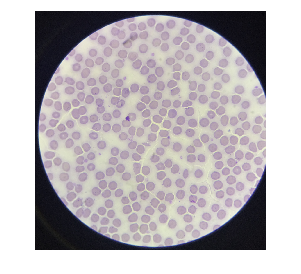

% load data
I = imread("22.jpg");
imshow(I)

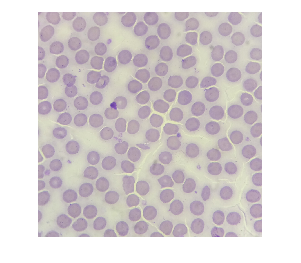

% crop out any black space in the picture which messes up thresholding
% (consistent for this data set)
cropsize = [2000,2000];
r = centerCropWindow2d(size(I),cropsize);
I =imcrop(I,r);
imshow(I)

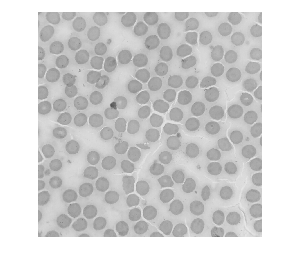

% grayscale
I = rgb2gray(I);
imshow(I);

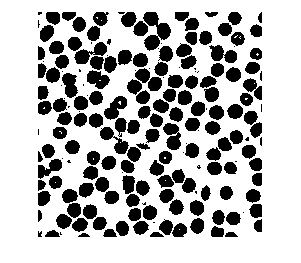

% binarize
level = graythresh(I);
Ibinary = im2bw(I, level);
imshow(Ibinary)

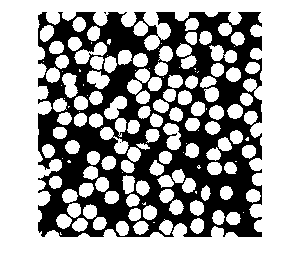

% fill holes
Ibinary = imfill(~Ibinary, 'holes');
imshow(Ibinary)

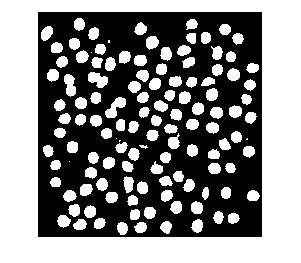

% clear border
Icl = imclearborder(Ibinary);
% erode and open to mitigate overlap
seD = strel('diamond',10);
Ierode = imerode(Icl,seD);
imshow(Ierode)

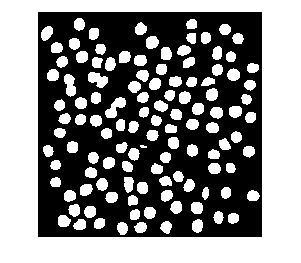

se = strel('disk', 10); 
Iopen = imopen(Ierode, se);
imshow(Iopen)

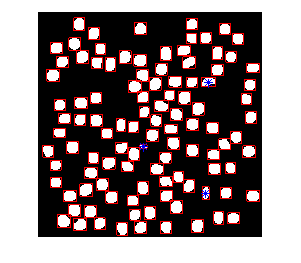

% remove objects that are too small or too large
Irange = bwareafilt(Iopen, [100 10000]);
imshow(Irange)
% label all objects
[L, n] = bwlabel(Irange);
% find centroids, representative box, and side lengths for all objects
s = regionprops(L, 'Centroid','BoundingBox','MajorAxisLength','MinorAxisLength');
% redefine centroid points into easily called variables
C = [s.Centroid];
centroidx = C(1:2:length(C));
centroidy = C(2:2:length(C));
% redefine representative box information into easy variables
BB= [s.BoundingBox];
xcorner = BB(1:4:length(BB));
ycorner = BB(2:4:length(BB));
xwidth = BB(3:4:length(BB));
ywidth = BB(4:4:length(BB));
% reconfigure maximum length data for each object
mx = [s.MajorAxisLength];
% reconfigure minimum length data for each object
mn = [s.MinorAxisLength];
% calculate the difference between lengths
sub = mx-mn;
% Calculate the "form factor," our determining information about healthy
% and unhealthy cells
factor = mx./sub;
% define cells with low form factors as sickle
sickle = factor<2.3;
% show object identifiers and label sickle cells with asterisks.
for i= 1:1:length(xcorner)
    rectangle('Position', [xcorner(i) ycorner(i) xwidth(i) ywidth(i)], 'Edgecolor', 'r');
    if sickle(i) > 0
        hold on
        plot(centroidx(i),centroidy(i),'b*');
        hold off
    end
end

% count how many normal cells there are
countnormal = length(xcorner) - sum(sickle);
% output results
if sum(sickle) > 0
    fprintf('The blood smear shows %d sickle cells',sum(sickle))
else
    fprintf('The blood smear is clean')
end

The blood smear shows 3 sickle cells

fprintf('There are %d normal blood cells', countnormal);

There are 102 normal blood cells